# Rotating around an axis

To get faminiar with **patch** and plotting a cube visit: 

- https://es.mathworks.com/help/matlab/ref/patch.html

- https://es.mathworks.com/help/matlab/visualize/multifaceted-patches.html#f2-18543

## Vertices and faces of a cube

clear
v= [0 0 0;1 0 0;1 1 0;0 1 0;0 0 1;1 0 1;1 1 1;0 1 1]

v =      0     0     0
     1     0     0
     1     1     0
     0     1     0
     0     0     1
     1     0     1
     1     1     1
     0     1     1


f = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8]

f =      1     2     6     5
     2     3     7     6
     3     4     8     7
     4     1     5     8
     1     2     3     4
     5     6     7     8


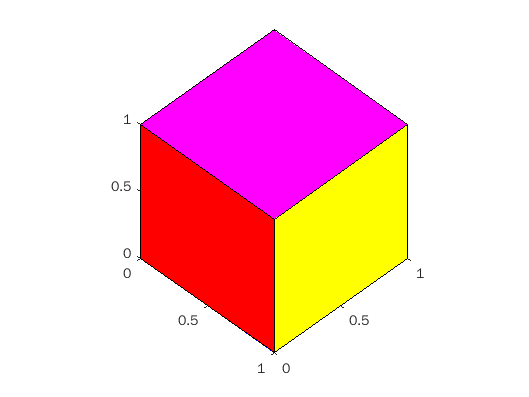

patch('Vertices',v,'Faces',f,'FaceVertexCData',hsv(6),'FaceColor','flat')
view(45,45)
axis equal

## Rotating cube around Z axis

v_h=[v';ones(1,8)] % we transpose and add ones
rotacion=pi/2

v_h =      0     1     1     0     0     1     1     0
     0     0     1     1     0     0     1     1
     0     0     0     0     1     1     1     1
     1     1     1     1     1     1     1     1


N=20

rotacion = 1.5708

for i=1:N

N = 20

    R_B_A=trotz(i*rotacion/N);
    v_h_p=R_B_A*v_h;
    v_p=v_h_p(1:3,:)';
    plotvol([-1.5 1.5 -1.5 1.5 0 1 ])
    patch('Vertices',v_p,'Faces',f,'FaceVertexCData',hsv(6),'FaceColor','flat')
    view (45,45)
    drawnow
    %clf
end

## Rotating around any axis with ang/vect

N=20  
for i=1:N
    Ri = angvec2tr((i*pi/N), [1 1 1]);

N = 20

    v_h_p=Ri*v_h;
    plotvol([-1.5 1.5 -1.5 1.5 -1.5 1.5 ]);
    patch('Vertices',v_h_p(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','flat')
    arrow3([0 0 0],[1.5 1.5 1.5], '2.5s',1.5)
    view (45,45)
    drawnow
    %clf
   end

## Rotating around any axis with quaternions

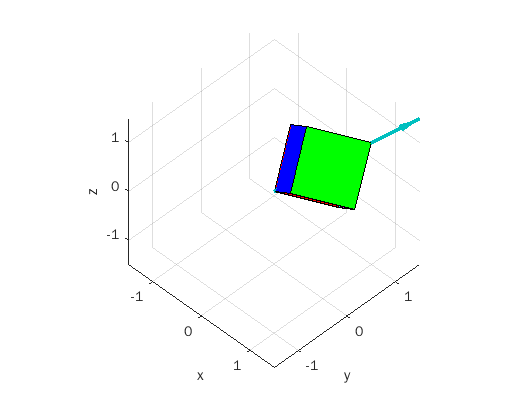

   N=20

   for i=1:N
    q4 = UnitQuaternion.angvec((i*pi/N), [0 1 1]);
    v_h_p=q4*v';
    plotvol([-1.5 1.5 -1.5 1.5 -1.5 1.5 ]);
    patch('Vertices',v_h_p','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','flat')
    arrow3([0 0 0],[0 1.5 1.5], '2.5s',1.5)
    view (45,45)
    drawnow
    %clf
   end